.

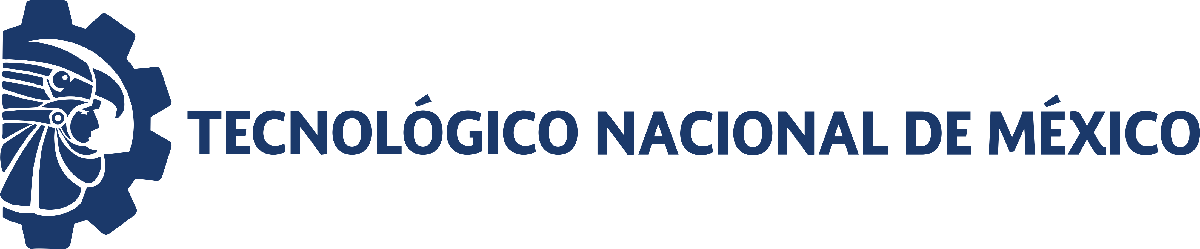                                 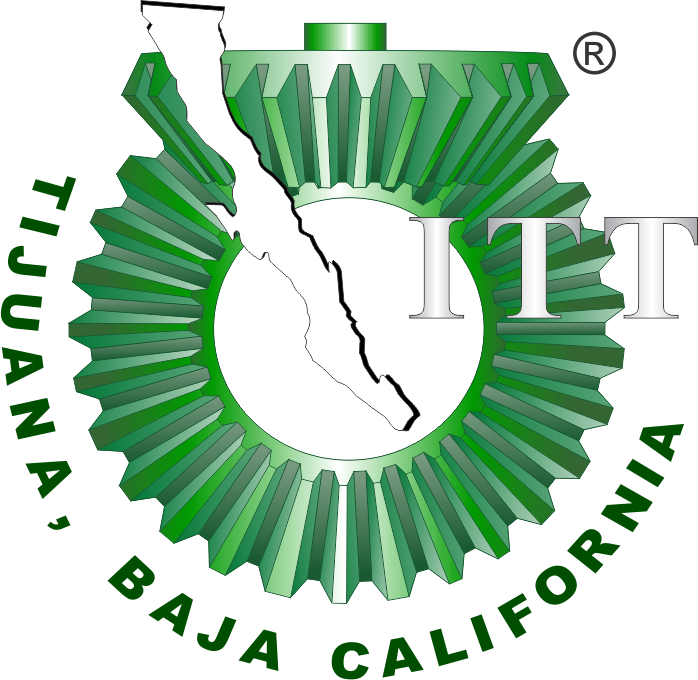

# Práctica dos: Modelado y control del sistema cardiovascular medianteel modelo Windkessel

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

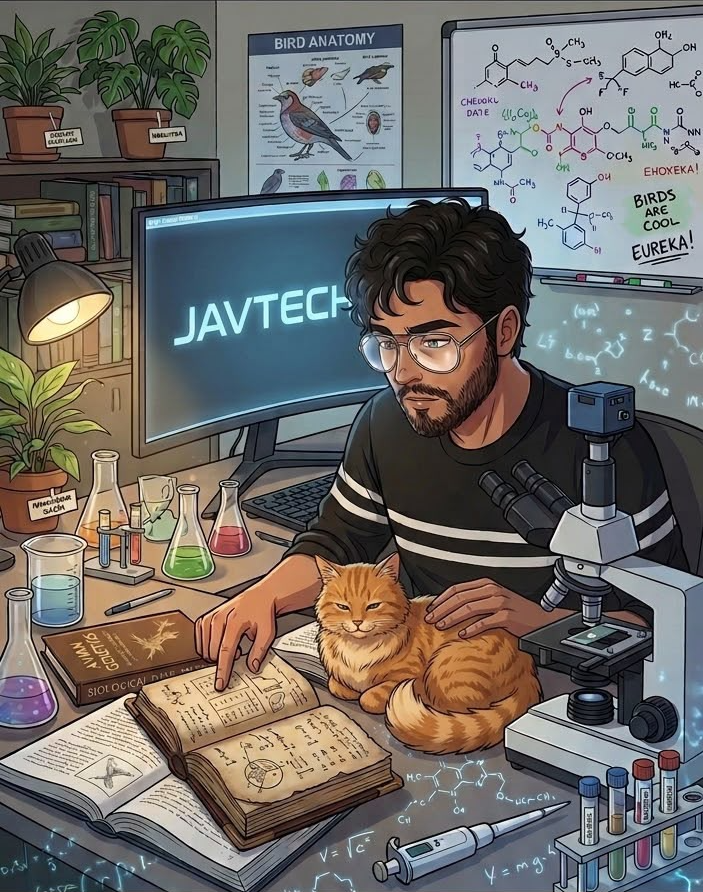

Nombre del alumno: Javier Vazquez Gomez

Número de control: 23212242

Correo institucional: l23212242**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema')
parameters.StopTime = '15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-2';
x = sim('sistema', parameters)
t_data = (0:0.1:15)';
t = (0:0.1:15)';
Pa = interp1(t_data, x.Pa, t, 'previous')

Pa =     0.2420
    0.7735
   -0.0297
   -0.1102
    0.9630
    0.0147
    0.1512
    0.1324
   -0.0310
    0.4775
    0.2415
    0.9570
    0.2342
   -0.0913
   -0.0299


writematrix(Pa,'signal.xlsx');

## Normotenso

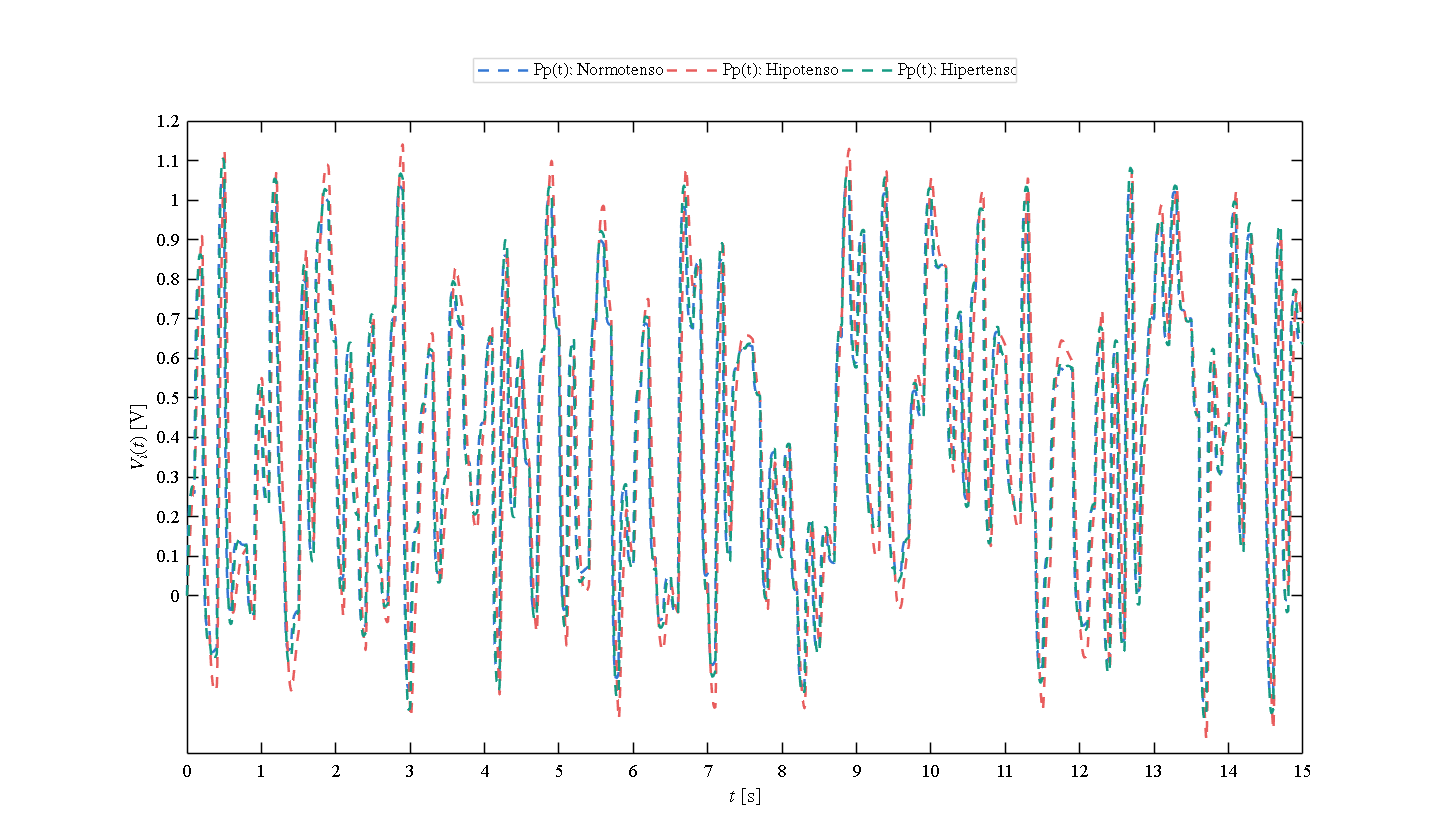

x = sim('sistema',parameters);
% Caso Normotenso
plotsignals(x.t, x.PpN, x.PpL, x.PpH, "Normotenso")

## Hipotenso

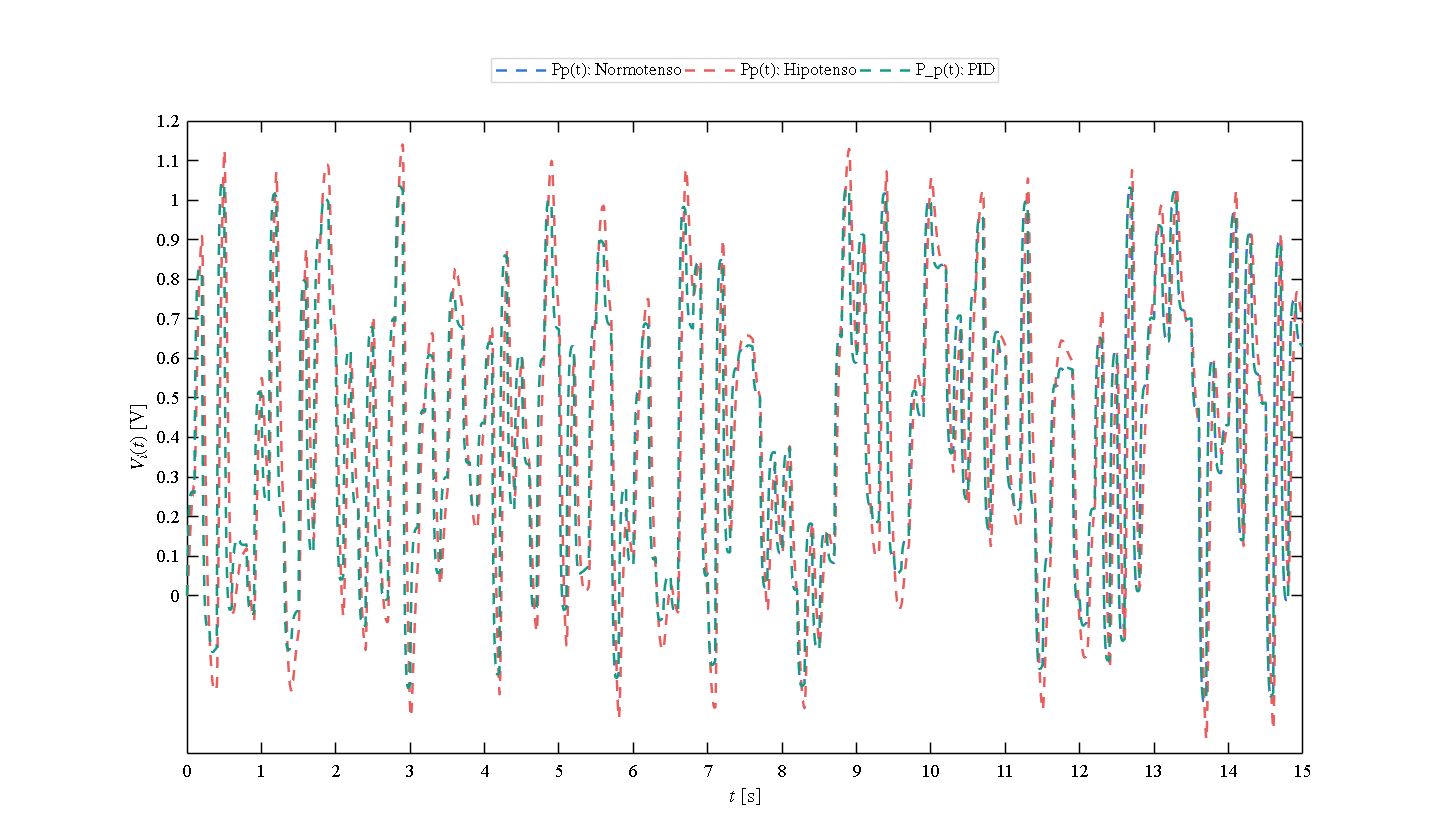

x1 = sim('sistema',parameters);

% Caso Hipotenso
plotsignals(x.t, x.PpN, x.PpL, x.PpH, "Hipotenso")

## Hipertenso

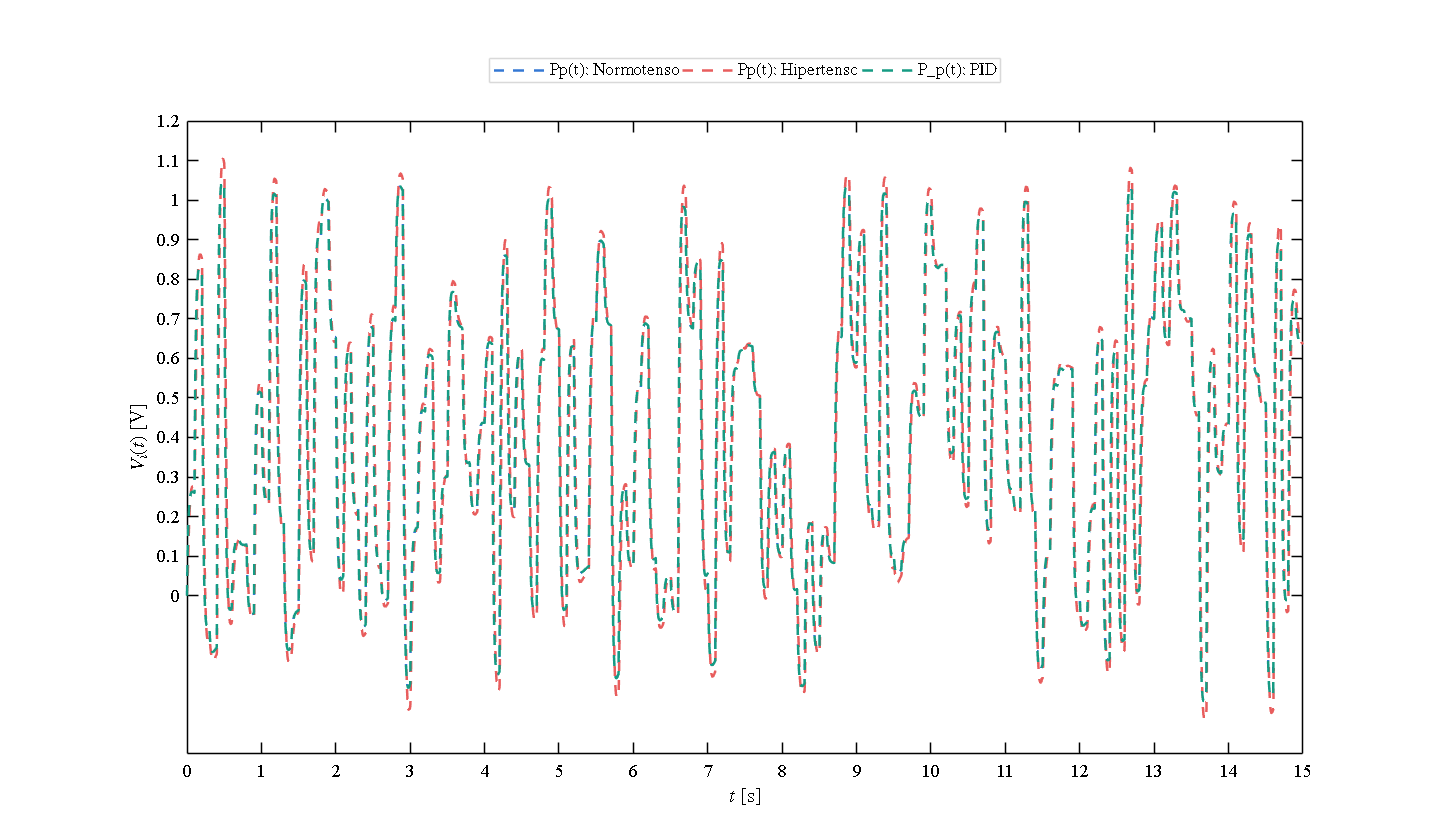

x2 = sim('sistema',parameters);
% Caso Hipertenso
plotsignals(x.t, x.PpN, x.PpL, x.PpH, "Hipertenso")

## Modelo de EDOs

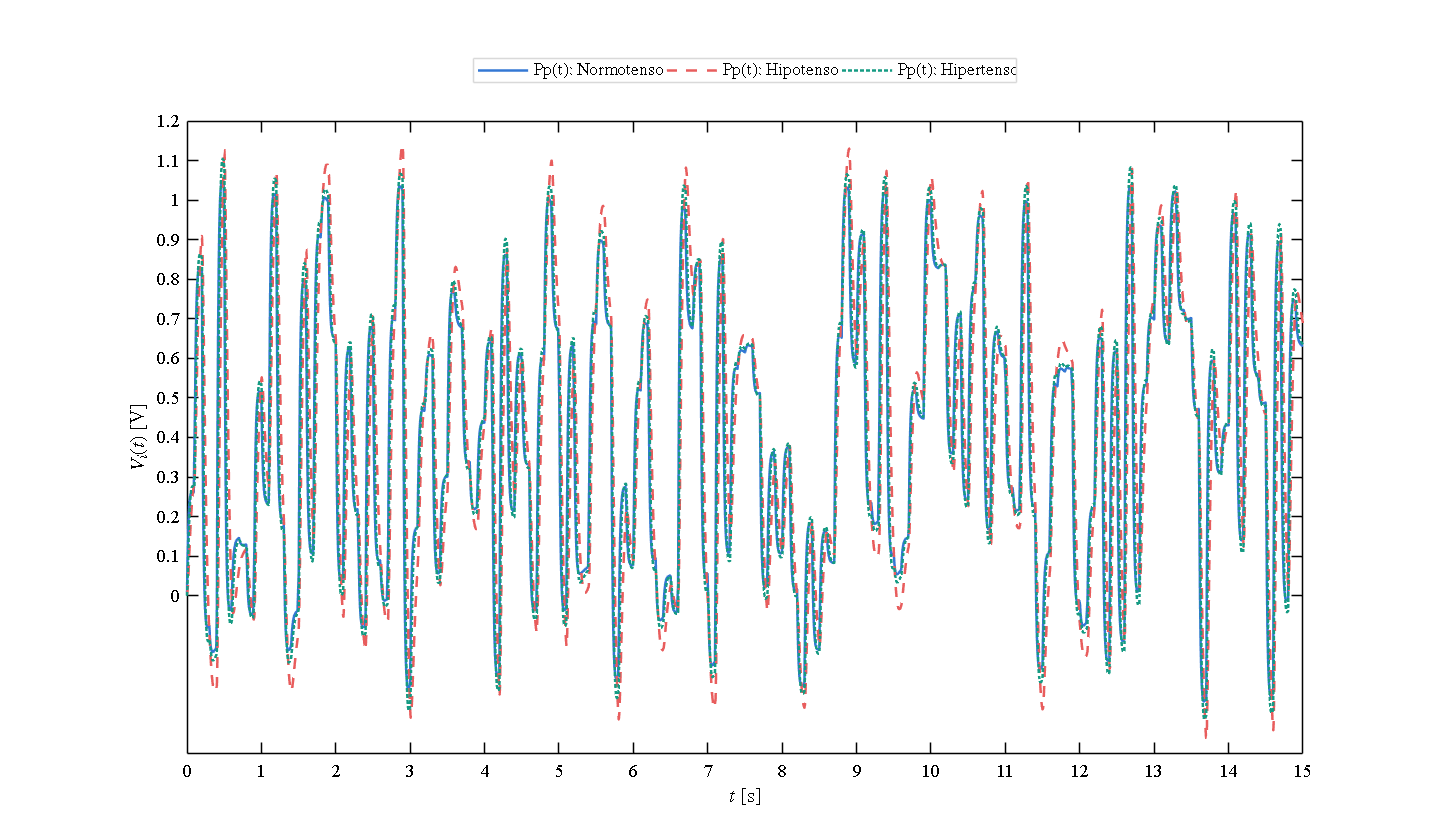

par_hipo = [0.010, 0.001,1.000,3.500]; %[Z,L,R]
par_normo = [0.010, 0.001,1.000,1.500];
par_hiper = [0.010, 0.001,1.000,1.000];

% Tiempo para resolver las EDOs
t = (0:1e-4:15)';

% Señal de entrada interpolada
Pa = interp1(t_data, x.Pa, t, 'previous');


PpN = cardio(par_normo, Pa, t);
PpL = cardio(par_hipo, PpN, t);
PpH = cardio(par_hiper, PpN, t);

plotsignals(t, PpN, PpL, PpH, 'individuos')



function Pp = cardio(par,Pa,t)
    Z = par(1); L = par(2); R = par(3); C = par(4);
    dt = t(2);
    n = round(t(end)/t(2));

    FL = zeros(length(t),1); FL(1) = 0;
    Pp = zeros(length(t),1); Pp(1) = 0;

    for i = 1:n
        FL (i+1) = FL(i) + (-(1/L)*Pp(i) + (1/L)*Pa(i))*dt;
        Pp(i+1) = Pp(i) + ((1/C)*FL(i)-(1/(Z*C)+ 1/(R*C))*Pp(i) + 1/(Z*C)*Pa(i))*dt;
    end
 end

## **Función: Respuestas de la simulación**

function plotsignals(t, PpN, PpL, PpH, signal)
    % Configuración visual de la ventana
    set(figure(), 'color', 'w');
    set(gcf, 'units', 'inches', 'position', [0.5, 0.5, 12, 7]);
    set(gca, 'fontname', 'times new roman', 'fontsize', 11);
    hold on; box on;
    
    clr1 = [52, 120, 212]/255;
    clr2 = [232, 93, 93]/255;
    clr3 = [21, 155, 131]/255;
    colororder([clr1; clr2; clr3]);

    xlabel('$t$ [s]', 'Interpreter', 'latex')
    ylabel('$V_i(t)$ [V]', 'Interpreter', 'latex')

    xlim([0 15]); xticks(0:1:15)
    ylim([-0.4 1.2]); yticks(0:0.1:1.2)

    % Evaluación según el parámetro 'signal' usando if / elseif
    if signal == "Normotenso"
        % Compara las tres respuestas fisiológicas básicas de Simulink
        plot(t, PpN, '--', t, PpL, '--', t, PpH, '--', ...
            'LineWidth', 1.5, 'MarkerIndices', 1:1e3:length(t));
        L = legend('Pp(t): Normotenso', 'Pp(t): Hipotenso', 'Pp(t): Hipertenso');
        
    elseif signal == "Hipotenso"
        % Extrae el PID internamente desde el workspace principal
        PIDL = evalin('base', 'x.PIDL'); 
        
        plot(t, PpN, '--', t, PpL, '--', t, PIDL, '--', ...
            'LineWidth', 1.5, 'MarkerIndices', 1:1e3:length(t));
        L = legend('Pp(t): Normotenso', 'Pp(t): Hipotenso', 'P_p(t): PID');
        
    elseif signal == "Hipertenso"
        % Extrae el PID internamente desde el workspace principal
        PIDH = evalin('base', 'x.PIDH'); 
        
        plot(t, PpN, '--', t, PpH, '--', t, PIDH, '--', ...
            'LineWidth', 1.5, 'MarkerIndices', 1:1e3:length(t));
        L = legend('Pp(t): Normotenso', 'Pp(t): Hipertenso', 'P_p(t): PID');

    elseif signal == "individuos"
        % Caso para las EDOs calculadas numéricamente con la función cardio
        plot(t, PpN, '-', t, PpL, '--', t, PpH, ':', ...
            'LineWidth', 1.5, 'MarkerIndices', 1:1e3:length(t));
        L = legend('Pp(t): Normotenso', 'Pp(t): Hipotenso', 'Pp(t): Hipertenso');
    end

    set(L, 'interpreter', 'latex', 'location', 'northoutside', 'orientation', 'horizontal');

    set(gcf,'Color','white')
    set(gca,'Color','white','XColor','black','YColor','black')
    set(L,'Color','white','TextColor','black')

    saveas(gcf, char(string(signal) + "_matlab.pdf"));
end